# Control design

This example shows how proportional damping ("P") and proportional-integral ("PI") controllers can be designed based on a WEC impedance and a sea state. The underlying code is based on a journal paper currently under review [1] and is hosted at [https://github.com/SNL-WaterPower/fbWecCntrl.](https://github.com/SNL-WaterPower/fbWecCntrl.)

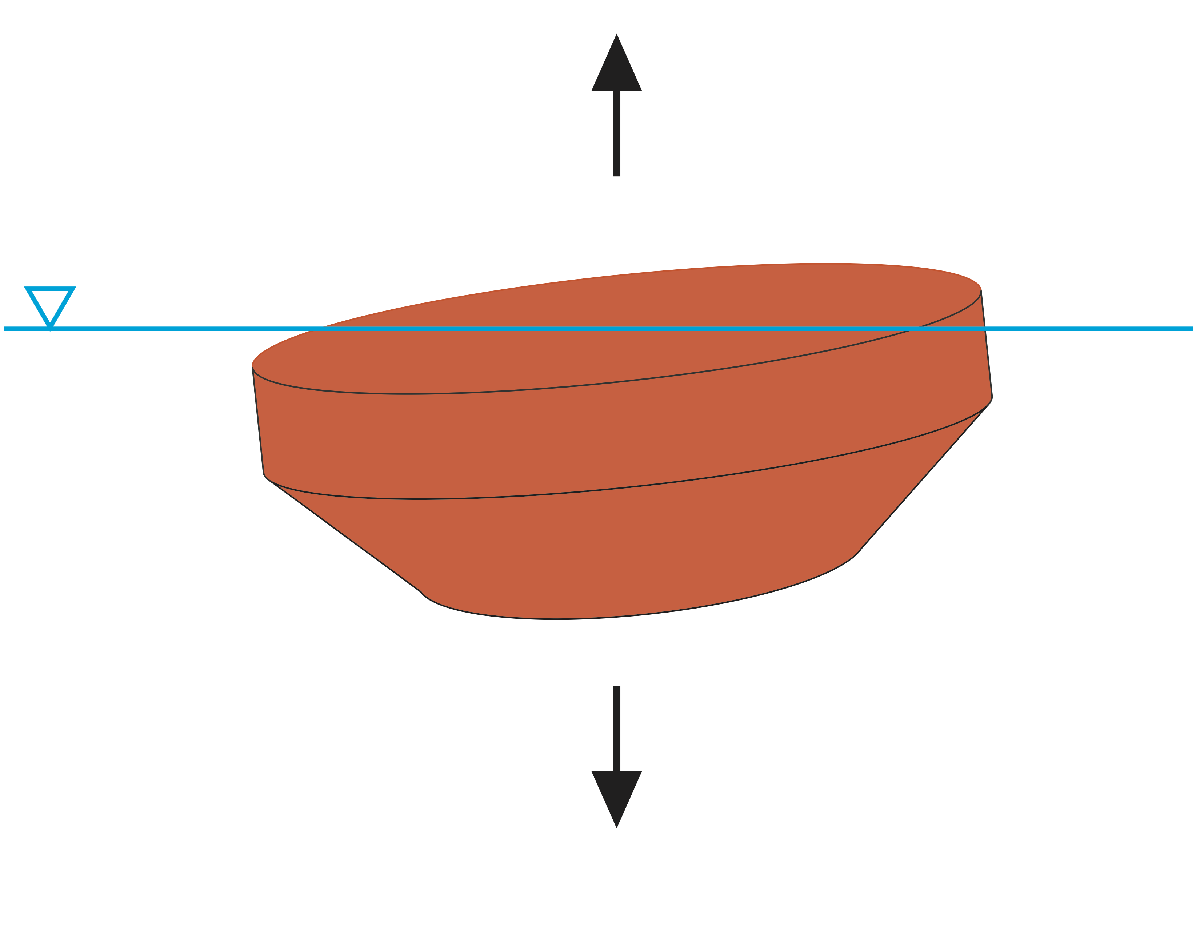

## Load WEC device model

We will use an empirically based model of the Sandia WaveBot in the heave mode.

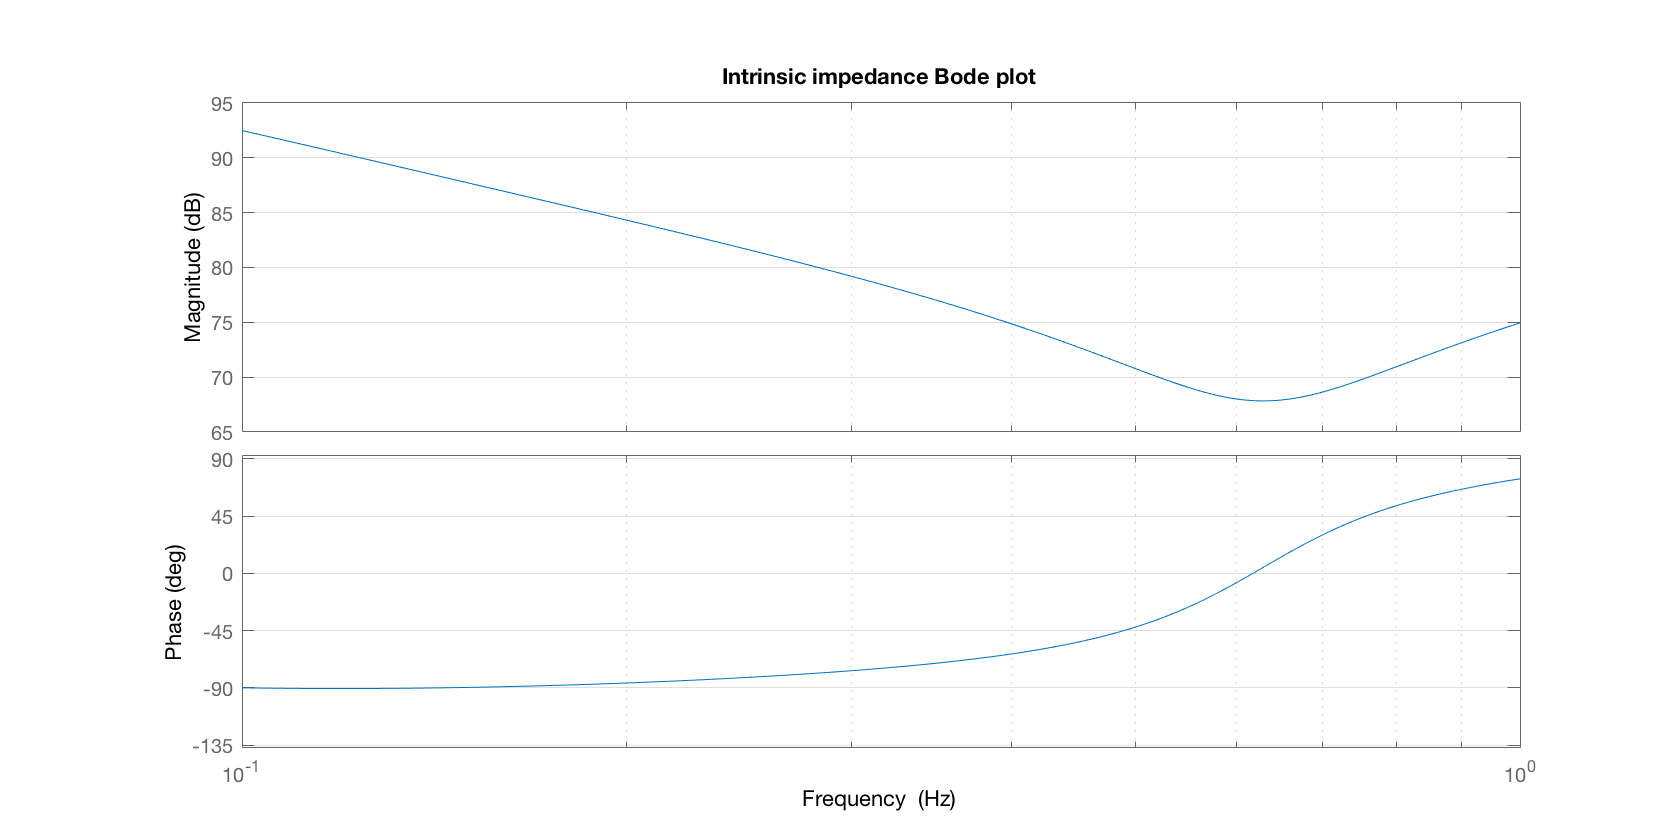

clc
clear
close all
mf = matfile(fullfile('data','waveBot_heaveModel.mat'));
Zi = shiftdim(mf.Zi_frf,-2);
Hex = transpose(mf.H_frf);
f = mf.f;

Kt = 7.1;
R = 0;
N = 12.4;

fig(1) = figure();
fig(1).Position = fig(1).Position .* [1 1 1.5 1];
h = bodeplot(frd(Zi,2*pi*f));
title('Intrinsic impedance Bode plot')
setoptions(h,'FreqUnits','Hz','Grid','on')

## Define sea state

We can define the sea state using the JONSWAP parametric definition based on significant wave height, peak period, and peakedness factor ("gamma").

Hm0 = 0.35; % 0.127
Tp = 3; % 3
gamma = 4.5; % 1.0

S = jonswap(2*pi*f,[Hm0, Tp, gamma]);

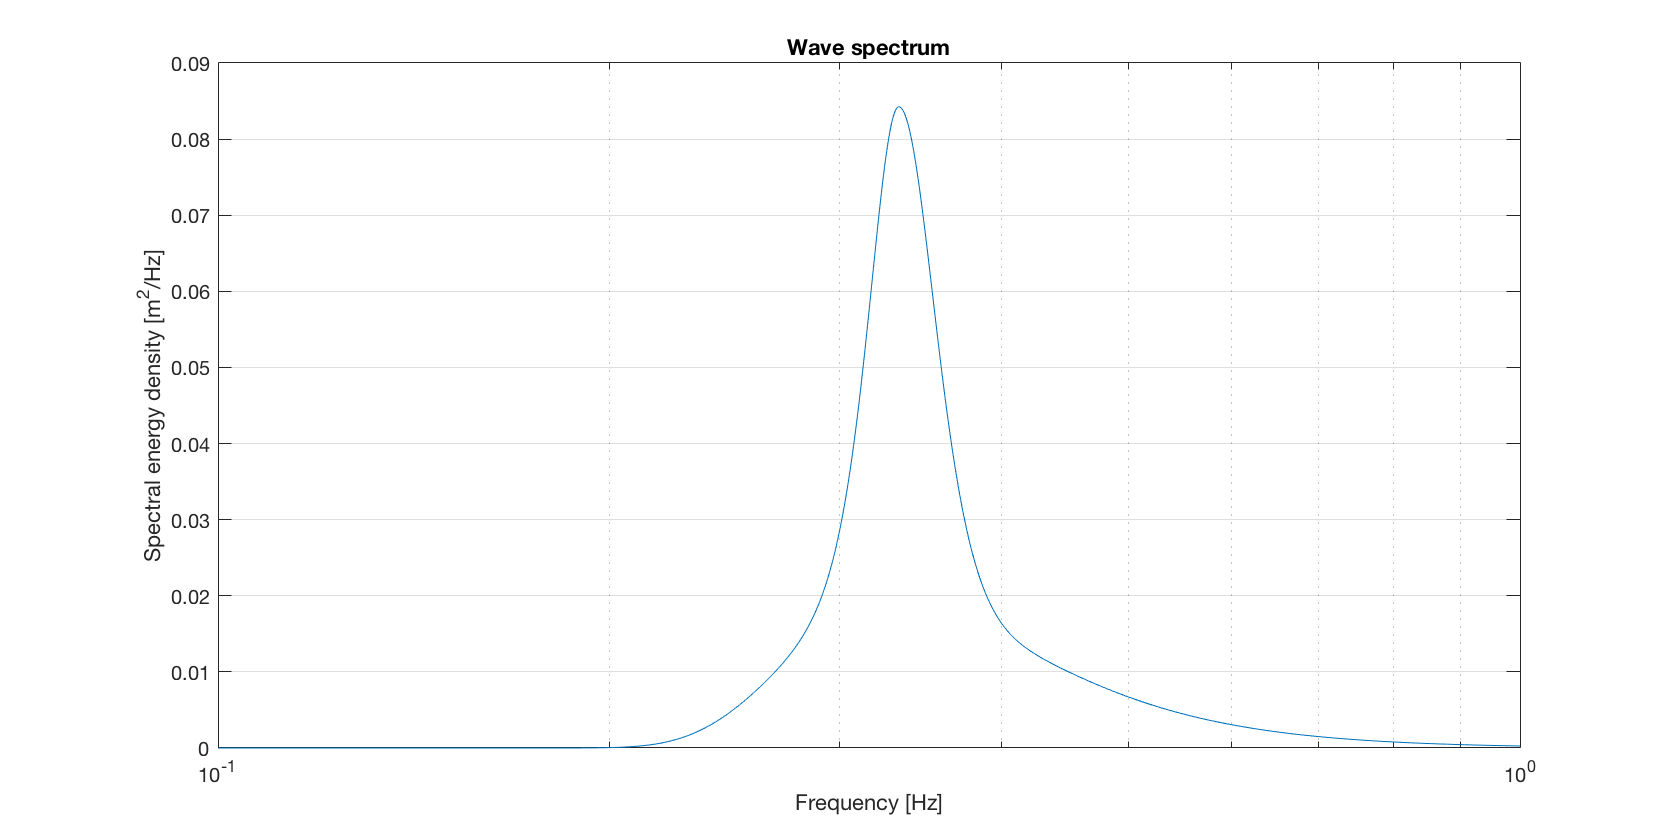

fig(2) = figure();
fig(2).Position = fig(2).Position .* [1 1 1.5 1];
plot(S.w/(2*pi), S.S*2*pi)
set(gca,'xscale','log')
xlabel('Frequency [Hz]')
ylabel('Spectral energy density [m^2/Hz]')
title('Wave spectrum')
grid on

## Run analysis

We can now *tune *(i.e., optimize) the controllers to produce as much power as possible in the given sea state. Since real ocean sea states change gradually (over the course of ~10 hours), we can monitor the wave conditions and slowly vary the controller settings to follow the changing sea state.


$$C_{opt} = \arg \min P(S(\omega), Z_i(\omega), C)$$


To perform the optimization, press "Run."

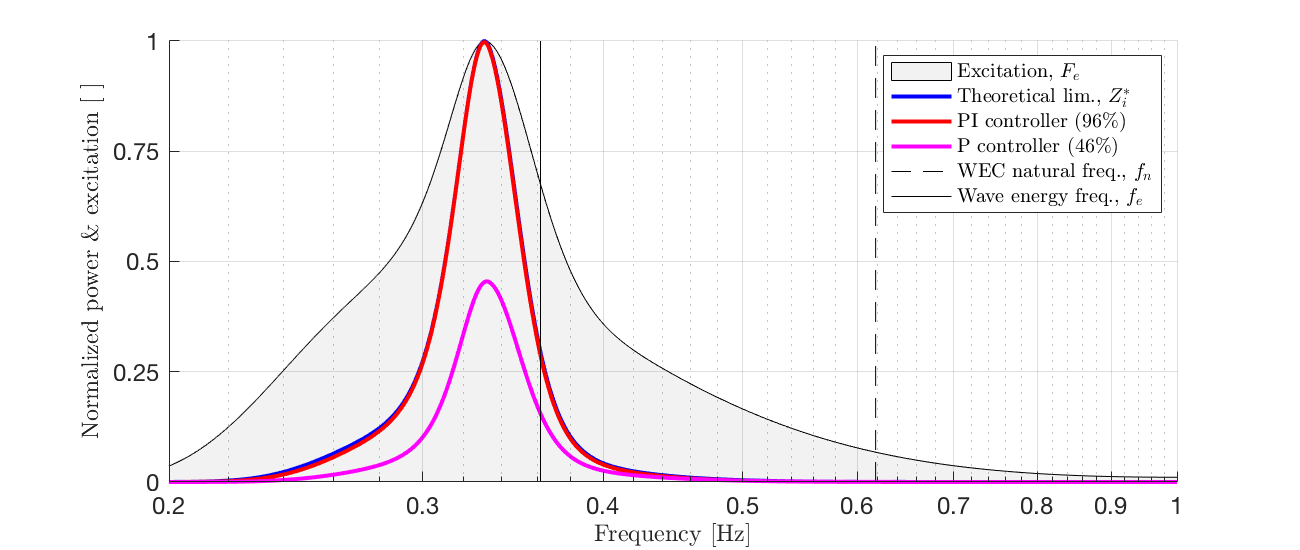

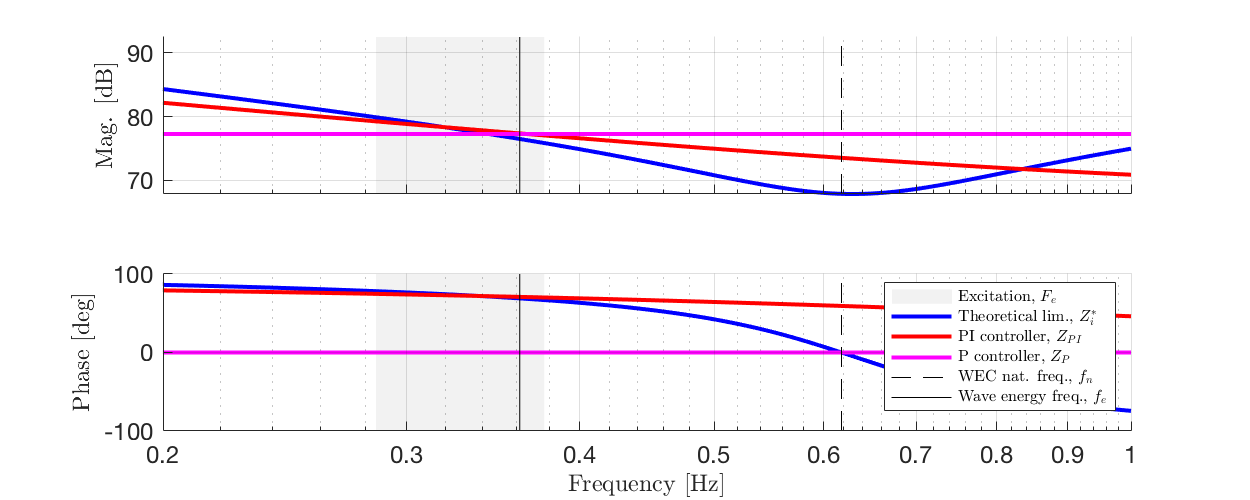

 
[powStudy,fh] = runPowStudy(f,Zi,Hex,S,'plotFlag',1,'Kt',Kt,'R',R,'N',N);
for ii = 1:length(fh)
    figure(fh(ii))
    xlim([0.2,1])
    set(gca,'xscale','log')
end

close(fh(1:2))

[1] Ryan G. Coe, Giorgio Bacelli, and Dominic Forbush. A practical approach to wave energy modeling and control. 9 2020b. doi: 10.36227/techrxiv.12939488.v1. URL [https://www.techrxiv.org/articles/ preprint/A_practical_approach_to_wave_energy_modeling_and_control/12939488](https://www.techrxiv.org/articles/ preprint/A_practical_approach_to_wave_energy_modeling_and_control/12939488)

% Copyright 2020 National Technology & Engineering Solutions of Sandia, 
% LLC (NTESS). Under the terms of Contract DE-NA0003525 with NTESS, the 
% U.S. Government retains certain rights in this software.
%
% This file is part of fbWecCntrl.
% 
%     fbWecCntrl is free software: you can redistribute it and/or modify
%     it under the terms of the GNU General Public License as published by
%     the Free Software Foundation, either version 3 of the License, or
%     (at your option) any later version.
% 
%     fbWecCntrl is distributed in the hope that it will be useful,
%     but WITHOUT ANY WARRANTY; without even the implied warranty of
%     MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the
%     GNU General Public License for more details.
% 
%     You should have received a copy of the GNU General Public License
%     along with fbWecCntrl.  If not, see <https://www.gnu.org/licenses/>.